# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.2  最优化

#### 3.2.2 Adagrad多元非线性回归

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

clear; clc;
% z = w1 * exp(-x / w2) + w3 * y + w4
% z = 900 * exp(-x / 2) + 50 * y + 10
len = 40;
rng('default');
x = randi(len + 1, len, 1) / 5;
y = randi(len + 1, len, 1) / 5;
z = 900 * exp(-x / 2) + 50 * y + 10;
maxi = max(z);
z = z / maxi;
ratio = 0.0;
z = z + ratio * max(z) * rand(len, 1);
X = [x, y];
fun = @(var, X)var(1) * exp(-X(:, 1) / var(2)) + var(3) * X(:, 2) + var(4);
w = lsqcurvefit(fun, [1, 1, 1, 1], X, z);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w([1, 3, 4]) = maxi * w([1, 3, 4]);
disp(['lsqcurvefit 计算结果：', num2str(w)]);

lsqcurvefit 计算结果：900             2            50      10.00001


% 梯度下降法学习
% obj = 1 / (2 * len) * (w1 * exp(-x / w2) + w3 * y  + w4 - z)' * (w1 * exp(-x / w2) + w3 * y + w4 - z)
alpha = 1;   % 学习率大收敛快，可能有震荡
iteMax = 10000;
w1 = 1;
w2 = 1;
w3 = 1;
w4 = 1;
initW = [w1; w2; w3; w4];
err = 1e-6;
J = zeros(iteMax, 1);
G = zeros(size(initW));
e = 0.1;
for i = 1 : iteMax
%     gradW1 = 1 / len * (exp(-x / w2))' * (w1 * exp(-x / w2) + w3 * y - z);
%     gradW2 = 1 / len * (w1 * x .* exp(-x / w2) / w2^2)' * (w1 * exp(-x / w2) + w3 * y - z);
%     gradW3 = 1 / len * y' * (w1 * exp(-x / w2) + w3 * y - z);
%     grad = [gradW1; gradW2; gradW3];
        gradW1 = exp(-x / w2);
        gradW2 = w1 * x .* exp(-x / w2) / w2^2;
        gradW3 = y;
        gradW4 = ones(len, 1);
        grad = 1 / len * [gradW1, gradW2, gradW3, gradW4]' * (w1 * exp(-x / w2) + w3 * y + w4 - z);
    % Adagrad 法    x = x + yita * inv(G) * grad;
    G = G + grad.^2;
    newW = initW - alpha * diag(1 ./ sqrt(G + e)) * grad;
    if norm(newW - initW) < err
        J(i + 1 : end) = [];
        disp(['梯度下降法迭代次数：', num2str(i)]);
        newW([1, 3, 4]) = maxi * newW([1, 3, 4]);
        disp(['梯度下降法迭代结果：', num2str(newW')]);
        break;
    else
        initW = newW;
        w1 = newW(1);
        w2 = newW(2);
        w3 = newW(3);
        w4 = newW(4);
        J(i) = 1 / (2 * len) * (w1 * exp(-x / w2) + w3 * y + w4 - z)' * (w1 * exp(-x / w2) + w3 * y + w4 - z);
    end
end

梯度下降法迭代次数：2968


梯度下降法迭代结果：900.0319      1.999579      49.99957      10.03015


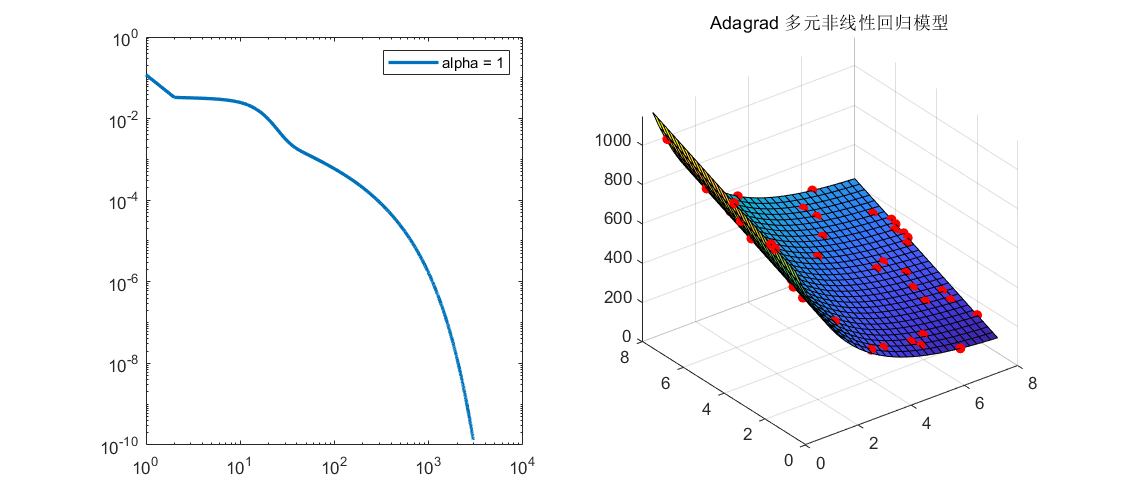

% 绘图
figure('Position', [50, 50, 900, 400]);
subplot(1, 2, 1)
loglog(J, 'LineWidth', 2)
legend(['alpha = ', num2str(alpha)]);
xFit1 = linspace(min(x), max(x), 30);
yFit1 = linspace(min(y), max(y), 30);
[xFit2, yFit2] = meshgrid(xFit1, yFit1);
zFit = w1 * exp(-xFit2 / w2) + w3 * yFit2 + w4;
zFit = maxi * zFit;
z = maxi * z;
subplot(1, 2, 2)
scatter3(x, y, z, 'r', 'filled');
hold on
surf(xFit2, yFit2, zFit);
hold off
title('Adagrad 多元非线性回归模型');